% Os dois primeiros exemplos são testes de conceito.

## Conexões não implementadas

Ainda não temos nenhuma conexão diferente de TCP.

Reserva para em caso no futuro seja desejável outras formas de conexão.

E para ajudar a desacoplar e permitir sobrecarga de métodos.

% try     
%     Analysers.Analyser.connGPIB('1234')
% catch exception
%     disp(exception.message)
% end

## Execução com o simulador SA2500PC

Alocação dinâmica ainda não implementada (perfumaria prevista):

Caso só passe o IP, teríamos uma opção de auto discovery:

% % Auto discovery
% try     
%     Analysers.Analyser.connTCP("localhost");
% catch exception
%     disp(exception.message)
% end
% 
% % Ref. portas a varrer:
% % 5025  - Keysight e R&S
% % 5555  - R&S EB500
% % 9001  - Anritsu
% % 34835 - Tektronix 

Instrumento simulado (Download em [SA2500PC](https://anatel365-my.sharepoint.com/:f:/r/personal/eric_anatel_gov_br/Documents/Softwares/Tektronix/SA2500PC?csf=1&web=1&e=Qde3u5)).

Conectado e respondendo à sua identificação:

% disp('Propriedades:')
% callTCP = Analysers.Analyser.connTCP("localhost", 34835) % Simulador
callTCP = Analysers.Analyser.connTCP("192.168.48.2", 34835)

callTCP =   dictionary (string ⟼ string) with 6 entries:

    "Factory" ⟼ "TEKTRONIX"
    "model"   ⟼ "SA2500"
    "serial"  ⟼ "B040211"
    "version" ⟼ "7.050"
    "ip"      ⟼ "192.168.48.2"
    "port"    ⟼ "34835"


## **Instância dinâmica. **

Cada fabricante deve ter, na pasta 'Analysers', sua classe como mesmo nome de sua superclasse (prop:Factory), e cada especifidade de um certo modelo (prop:model) deve estar com o mesmo nome, o que permite escalonar e isolar os componentes em uma interface unificada, e granularizada para o serviço esperado.

O 'Analyser' deve conter todos os comandos genéricos da SCPI (Standard Commands for Programmable Instruments) e IEEE 488.2 Common Commands, este último inicia por um asterisco..

Com base na IDN que o instrumento responde, a instância sempre herda todos os comandos do 'Analyser'.

No caso, o "is a" está representado no classdef como "classdef TEKTRONIX < Analyser", ou seja, Um Tektronix é um analisador, e o SP2500 é um Tektronx ("classdef SA2500PC < TEKTRONIX")

Neste caso herda os comuns e sobrecarrega os comandos do Tektronix, e os específicos do modelo SA2500PC:

disp('Instancia Classes:')

Instancia Classes:


obj = Analysers.Analyser.instance(callTCP);

    "Analyer: Base de comando do fabricante"    "TEKTRONIX"



O simulador fecha quando recebe o comando de reset, então só fingimos o reset para evitar isso (na implementação específica do modelo). O que ainda oportuna outros casos de uso em casos diferentes, como o EB500 que precisa abrir uma porta específica para receber stream UDP.

Um instrumento real não terá o sufixo PC e portanto automaticamente não herdará esse método, o que possibilita compartilar comandos e especificar no modelo o que for diferente nele.

Aplicando uma sobrecarga no modelo SA2500PC com a resposta da classe:

obj.scpiReset;

Analyer.scpiReset: Criando nova conexão TCP.


Comandos gerais de inicialização:

obj.startUp()

TEKTRONIX: Start Ok.


Teste geral de conectividade (SCPI):

obj.ping()

Analyser.ping: Mesma conexão
Analyser.ping: Resposta IDN recebida:
TEKTRONIX,SA2500,B040211,7.050


Obtém parâmetros do objeto: 

disp('getSpan:')

getSpan:


disp(obj.getSpan())

200000000



disp('Parâmetros:')

Parâmetros:


obj.getParms()

ans =   dictionary (string ⟼ string) with 10 entries:

    "Function"  ⟼ "NORM"
    "AVGCount"  ⟼ "20"
    "Detection" ⟼ "POS"
    "UnitPower" ⟼ "DBM"
    "FStart"    ⟼ "759000000"
    "FStop"     ⟼ "959000000"
    "ResAuto"   ⟼ "1"
    "Res"       ⟼ "200000"
    "InputGain" ⟼ "0"
    "Att"       ⟼ "50"


## Operação

Aqui perguntamos se o parâmetro corresponde ao que foi solicitado (assert). E verificamos as respostas no simulador em tempo real:

disp('Pausas para observar o comportamento:')

Pausas para observar o comportamento:



%pause(5) % tempo para ajuste manual de teste.


% % Testes
% obj.setFreq(120000000)
% obj.setSpan(50000)
% assert(str2double(obj.getSpan) == 50000, 'O Span não foi ajustado.')
% obj.setRes(2000)
% assert(str2double(obj.getRes) == 2000, 'O Span não foi ajustado.')
% 
pause(1)
obj.setFreq(100000000)
obj.setSpan(10000)

% disp('Nova conexão simulada pelo ping (caso não responda):')
% obj.conn = [];

% Isso gera um alerta na janela do simulador,
% mas não retorna erro.
% try
%     RBW = obj.getRes();
%     assert(str2double(RBW) == 2000, 'A Resolução foi alterada automaticamente.')
% catch exception
%     disp('Resolução alterada automaticamente para:')
%     disp(RBW)
% end

pause(1)
disp('Ajuste em faixa larga')

Ajuste em faixa larga


obj.setFreq(88000000, 108000000)
obj.setRes(20000) % Warning: Data out of range
% try
%     assert(str2double(obj.getSpan) == 10000, 'O Span não foi ajustado.')
% catch
%     disp('Se atribuir o span depois gera erro "out of range"')
% end

% pause(1)
% % Observar que o com Spectrum o RBW Auto em verde
% obj.setRes('Auto')
% obj.setFreq(88000000, 108000000)

% Para observar a faixa em auto level
pause(3)
% Escolhe uma portadora FM para análise
freq = 100300000;

obj.setSpan(500000)
obj.setFreq(freq)
assert(str2double(obj.getSpan) == 500000, 'O Span não foi ajustado.')

% Cuidado! Os pisos não correspondem aos de um instrumento real!

%obj.preAmp('On')

% % Teste dos níveis de atenuação (comentado para poupar tempo)
% % Para observar abrir o menu Spectrum -> More -> Ampl
% for attstep = 5:5:50
%     obj.setAtt(attstep);
%     pause(0.5)
% 
%     % O pré desativa sozinho com att acima de 15dB
%     % Mesmo expressamente solicitado, sem erro:
%     obj.preAmp('On')
% end


Trace:


       freq        value 
    __________    _______

    1.0005e+08    -118.07
    1.0005e+08    -118.73
    1.0005e+08    -121.49
    1.0005e+08    -120.85
    1.0005e+08    -115.97



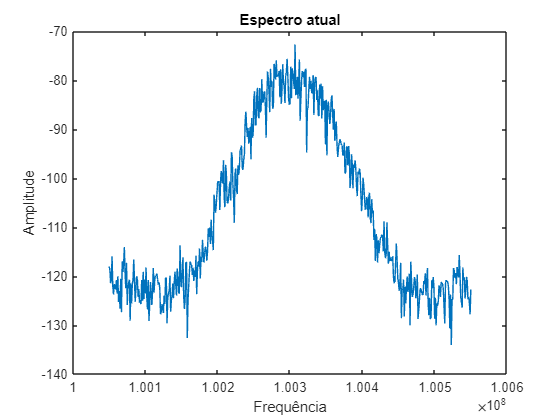

Leitura do marcador:


ans = 'Em 100300000 MHz o nível é: -90.636063'


% Esse bloco try é para liberar a conexão em caso de erro.
try
    trace = obj.getTrace(1);

    disp('Trace:')
    
    
    
    % Só as 5 primeiras linhas
    disp(trace (1:5,:));
    
    
    
    % Plota o Trace
    p = plot(trace.freq,trace.value,"DisplayName","value");
    
    % Add xlabel, ylabel, title, and legend
    xlabel("Frequência")
    ylabel("Amplitude")
    title("Espectro atual")
    legend('off');
    
    disp('Leitura do marcador:')
    nivel = obj.getMarker(freq, 1);
    sprintf('Em %i MHz o nível é: %f', freq, nivel)
    

    disp('Adquirindo os traços com 3s de delay.');

Adquirindo os traços com 3s de delay.


    disp('Para amenizar problemas de sinc.')

Para amenizar problemas de sinc.


    trcs = fcn.getTracesFromUnit(obj, 10);

ans = "Trace nº 1"

ans = "Trace nº 2"

ans = "Trace nº 3"

ans = "Trace nº 4"

ans = "Trace nº 5"

ans = "Trace nº 6"

ans = "Trace nº 7"

ans = "Trace nº 8"

ans = "Trace nº 9"

ans = "Trace nº 10"


    disp("Total size:")

Total size:


    size(trcs)

ans =     10   501


    disp(trcs)

 -120.5881 -127.6184 -118.2587 -117.9575 -122.1557 -118.3135 -123.8988 -131.7202 -127.8473 -126.8056 -122.3191 -121.2279 -131.9389 -122.9396 -125.8265 -130.4172 -128.0241 -120.3644 -121.0837 -117.5666 -125.5970 -122.9988 -124.6769 -120.2400 -122.1149 -121.5849 -117.1868 -122.6174 -119.2637 -123.4414 -119.9482 -121.7085 -119.9043 -126.3965 -121.3005 -129.3402 -125.1647 -128.0653 -119.6185 -126.6735 -127.5291 -123.0335 -119.5597 -117.3793 -121.8388 -117.6227 -121.2733 -123.2308 -124.6655 -119.7736 -118.6049 -115.4759 -118.6765 -122.6132 -124.2569 -127.2727 -122.7891 -123.9956 -120.0216 -119.2633 -117.1360 -121.8449 -119.6539 -121.8756 -121.6191 -129.1502 -123.4498 -119.7946 -125.9184 -128.1148 -124.2063 -122.2069 -127.1799 -118.3503 -122.2630 -127.5767 -124.4389 -119.4987 -125.3158 -124.9673 -125.7834 -121.7331 -119.5789 -124.1624 -120.4424 -125.4685 -121.8184 -119.5706 -127.4111 -122.3792 -127.6599 -119.9621 -126.0199 -123.1123 -116.6116 -117.4664 -116.6913 -122.7783 -122.4577 -115.2898


catch exception
    % Encerra ativamente a conexão
    % Para liberar a porta em caso de erro
    obj.disconnect();
    error('TestTektronix: %s', exception.identifier);
end

% Se tudo der certo, encerra a conexão.
obj.disconnect()


disp("Pronto")

Pronto
